# **Anti-reflection coating**

     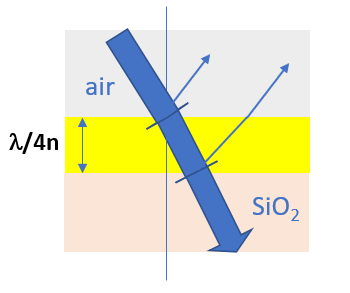

## Data 

% Refractive indices
n_air = 1; 
n_subtrat = 1.5; 
n_layer = sqrt(n_air*n_subtrat);
index = [n_air n_layer n_subtrat]; %  [supstrat layers substrat]
%
% Geometry
wl = .6; % Wavelength reference (µm)
geom = wl/(4*n_layer); % Layer Thickness (µm)
%

## Spectrum Computation versus wavelength

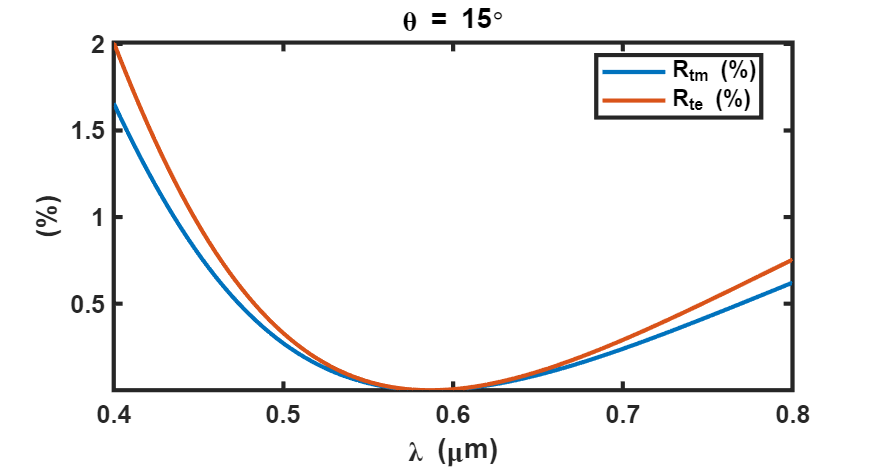

% Incident Plane Wave
lambda = linspace(0.4,0.8,101); % Wavelength(µm)
theta = 15*pi/180;              % Incident angle (rd)
inc = +1; % inc = -1: from down, +1: from top
%
% Spectrum Computation versus wavelength (lambda) for a defined incident angle 
[R_tm,T_tm,R_te,T_te] = Spectrum(index,geom,lambda,theta,inc);
%
% Plot Reflection versus wave-length in TM and TE polarisation 
figure('Position',[300  300  560  300]), 
PlotCoefRTA(lambda,theta,R_tm,R_te), legend('R_{tm} (%)','R_{te} (%)'), axis tight

## Spectrum Computation versus incident angle

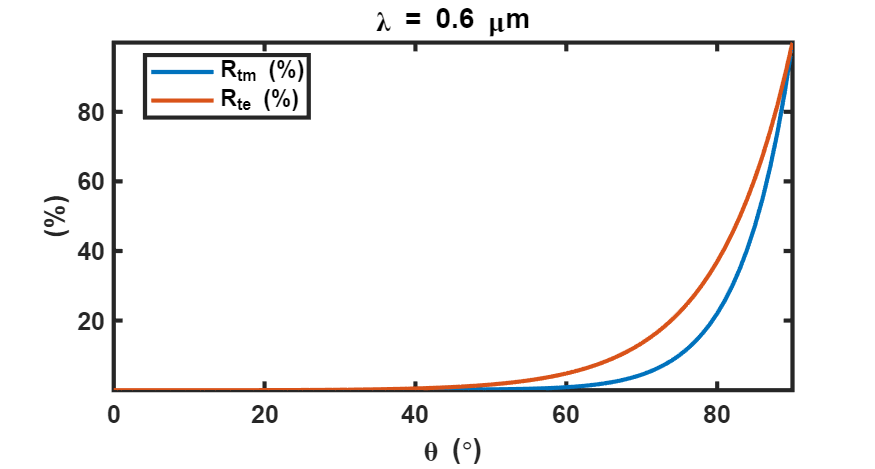

% Incident Plane Wave
lambda = 0.6; 
theta = linspace(0,89.99,91)*pi/180; 
inc = +1; % inc = -1: from down, +1: from up
%
% Spectrum Computation versus incident angle (theta) for a defined wavelength
[R_tm,T_tm,R_te,T_te] = Spectrum(index,geom,lambda,theta,inc);
%
% Plot Reflection versus wavelength in TM and TE polarisation 
figure('Position',[300  300  560  300]), 
PlotCoefRTA(lambda,theta,R_tm,R_te), legend('R_{tm} (%)','R_{te} (%)'), axis tight

## Field Computation for TM and TE polarizations 

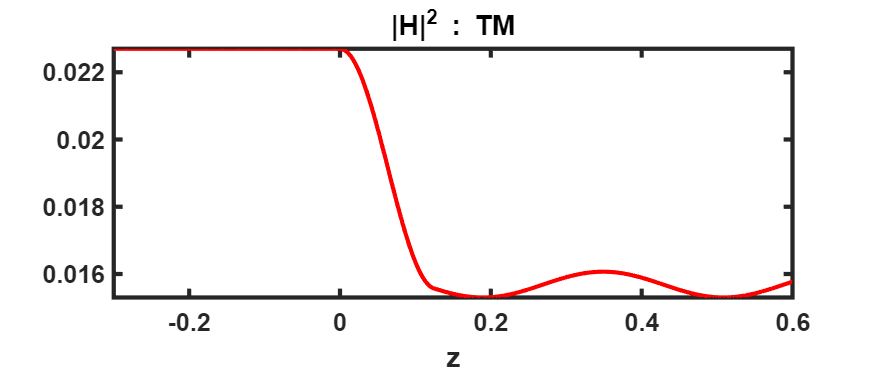

lambda = 0.6; 
theta = 20*pi/180; 
inc = +1; % inc = -1: from down, +1: from up
%
[x0,y0,z0] = deal(0,0,linspace(-.3,.6,201)); % along z-axis
%
% Field calculation : first method
s = Spectrum(index,geom,lambda,theta,inc);
[E,H] = CalculFieldFMM(s,x0,y0,z0);         

% % Field calculation : second method
%geom = SetGeom('hc',wl/(4*n_layer),'x',x0,'y',y0,'z',z0)
%[E,H] = Field(index,geom,lambda,theta,inc);


% Plot Field distribution
figure('Position',[300  300  560  240]), hold on
VisuFieldFMM(sum(abs(H(:,1:3)).^2,2),x0,y0,z0),axis tight,title('|H|^2 : TM')

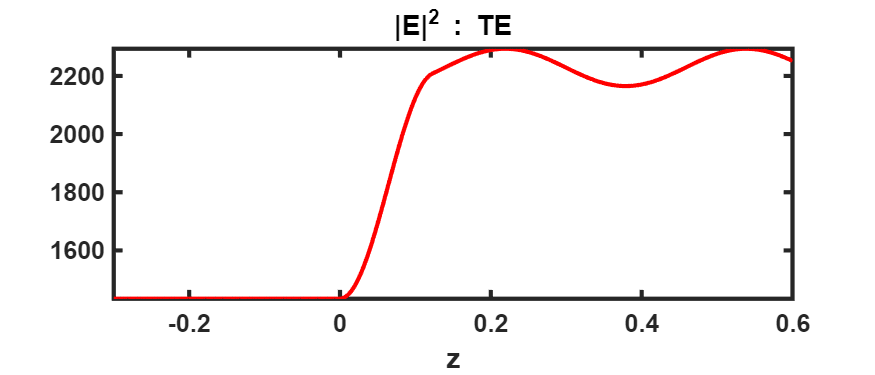

figure('Position',[300  300  560  240]), 
VisuFieldFMM(sum(abs(E(:,4:6)).^2,2),x0,y0,z0), axis tight,title('|E|^2 : TE') 